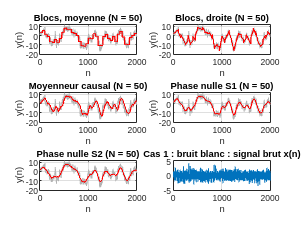

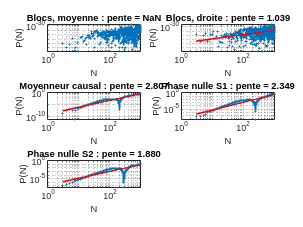

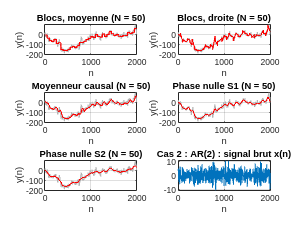

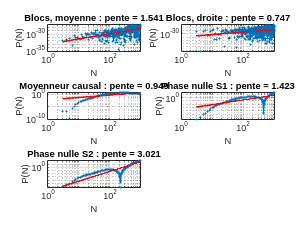

clear; close all; clc;
M = 2000;
noms = {'Blocs, moyenne','Blocs, droite','Moyenneur causal', ...
        'Phase nulle S1','Phase nulle S2'};

% Cas 1 : bruit blanc gaussien centre
x1 = randn(M,1);
% Cas 2 : AR(2) (poles de module sqrt(0.7) < 1, donc stable)
x2 = filter(1, [1 -1.5 0.7], randn(M,1));

cas = {x1, x2};
nomCas = {'Cas 1 : bruit blanc', 'Cas 2 : AR(2)'};
Nvis = 50;   % valeur de N utilisee pour visualiser les tendances

for c = 1:2
    x = cas{c};
    xc = x(:)- mean(x);
    y = cumsum(xc);                       % etape 1

    % --- Figure A : signal integre et tendances pour un N donne ---
    figure('Name', [nomCas{c} ' - tendances']);
    for m = 1:5
        t = tendances(y, Nvis, m);
        subplot(3,2,m);
        plot(y, 'Color', [0.7 0.7 0.7]); hold on;
        plot(t, 'r', 'LineWidth', 1.2);
        title(sprintf('%s (N = %d)', noms{m}, Nvis));
        xlabel('n'); ylabel('y(n)'); grid on;
    end
    subplot(3,2,6);
    plot(x); title([nomCas{c} ' : signal brut x(n)']);
    xlabel('n'); grid on;

    % --- Figure B : log-log et droite de regression, par methode ---
    figure('Name', [nomCas{c} ' - log-log']);
    for m = 1:5
        [pente, Ns, P, p] = marqueur(x, m, 1);
        subplot(3,2,m);
        loglog(Ns, P, '.', 'MarkerSize', 6); hold on;
        loglog(Ns, exp(polyval(p, log(Ns))), 'r', 'LineWidth', 1.5);
        title(sprintf('%s : pente = %.3f', noms{m}, pente));
        xlabel('N'); ylabel('P(N)'); grid on;
    end
end

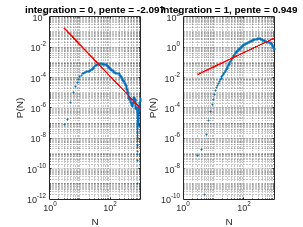


% --- Figure C : avec / sans integration (cas 2 par exemple) ---
figure('Name', 'Effet de l''integration');
for i = 0:1
    [pente, Ns, P, p] = marqueur(x2, 3, i);
    subplot(1,2,i+1);
    loglog(Ns, P, '.'); hold on;
    loglog(Ns, exp(polyval(p, log(Ns))), 'r', 'LineWidth', 1.5);
    title(sprintf('integration = %d, pente = %.3f', i, pente));
    xlabel('N'); ylabel('P(N)'); grid on;
end